clear all;

%x = featureExtract("Data/genres_original/blues/blues.00000.wav")
for ii = 0:99
    A = sprintf('Data/genres_original/rock/rock.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+1,:) = feature;
    label(ii+1) = "rock";
end
for ii = 0:99
    A = sprintf('Data/genres_original/classical/classical.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+101,:) = feature;
    label(ii+101) = "classical";
end
for ii = 0:99
    A = sprintf('Data/genres_original/pop/pop.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+201,:) = feature;
    label(ii+201) = "pop";
end
for ii = 0:99
    A = sprintf('Data/genres_original/metal/metal.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+301,:) = feature;
    label(ii+301) = "metal";
end

trainingVector = randi([1 400], [350 1]);
for ii = 1:350
    trainingDataset(ii,:) = features(trainingVector(ii),:);
    trainingLabel(ii) = label(trainingVector(ii));
end

testingVector = randi([1 400], [50 1]);
for ii = 1:50
    testingDataset(ii, :) = features(testingVector(ii),:);
    testingLabel(ii) = label(testingVector(ii));
end
trainingLabelCategorical = categorical(trainingLabel');
testingLabelCategorical = categorical(testingLabel');

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |       27.34% |       18.00% |       3.2108 |       3.2034 |          0.0010 |
|       2 |           3 |       00:00:06 |       31.25% |       18.00% |       2.7099 |       2.7840 |          0.0010 |
|       3 |           6 |       00:00:06 |       25.00% |       16.00% |       2.3537 |       2.2622 |          0.0010 |
|       5 |           9 |       00:00:06 |       28.91% |       30.00% |       1.8815 |       1.8913 |          0.0010 |
|       6 |          12 |       00:00:06 |       39.84% |       56.00% |       1.6842 |       1.6510 |          0.0010 |
|       8 |          15 |       00:00:06 |       43.75% |       56.00% |       1.6756 |       1.4970 |          0.0010 |
|       9 |          18 |       00:00:06 |       45.31% |       54.00% |       1.5672 |       1.3773 |          0.0010 |
|      11 |          21 |       00:00:06 |       44.53% |       54.00% |       1.3546 |       1.2658 |          0.0010 |
|      12 |          24 |       

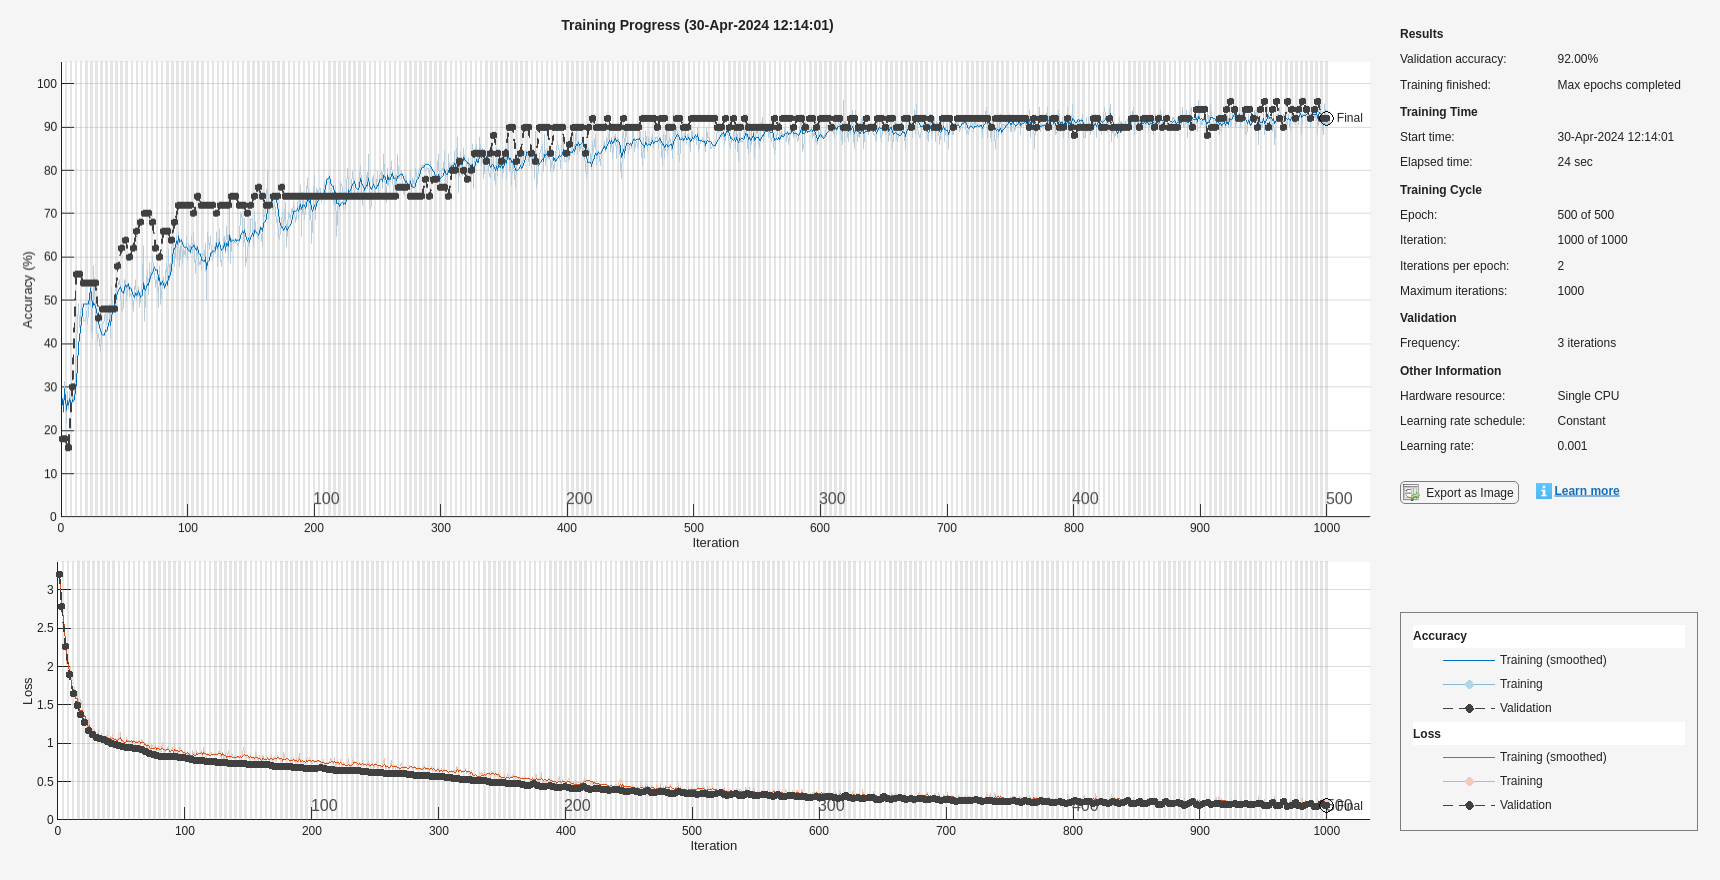

layers = [
    featureInputLayer(56)
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer
];

options = trainingOptions("adam", ...
    InitialLearnRate=0.001, ...
    MaxEpochs=500, ...
    Shuffle="every-epoch", ...
    ValidationData={testingDataset,testingLabelCategorical}, ...
    ValidationFrequency=3,...
    Plots="training-progress");
clear net;
net = trainNetwork(trainingDataset,trainingLabelCategorical,layers,options);

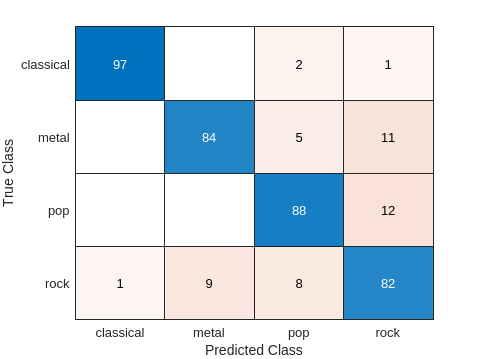

guess = zeros(400,1);
for ii = 1:400
    predictions(ii,:) = predict(net, features(ii,:));
    [maxVals(ii), guess(ii)] = max(predictions(ii,:));
end

for ii = 1:400
    if guess(ii) == 1
        predictedLabel(ii) = "classical";
    end
    if guess(ii) == 2
        predictedLabel(ii) = "metal";
    end
    if guess(ii) == 3
        predictedLabel(ii) = "pop";
    end
    if guess(ii) == 4
        predictedLabel(ii) = "rock";
    end
end
confusionchart(label, predictedLabel)


sampleGuess = predict(net,featureExtract("classicalSample.mp3"));
[sampleMax, sampleGuess] = max(sampleGuess);
if sampleGuess == 1
    disp("classical")
end
if sampleGuess == 2
    disp("metal")
end
if sampleGuess == 3
    disp("pop")
end

pop


if sampleGuess == 4
    disp("rock");
end

function  featureVector = featureExtract(x)

    % Step 1: Specify the WAV file
    
    filename = x;
    
    % Check if file exists
    if ~isfile(filename)
        error('File does not exist. Check the filename and try again.');
    end
    
    % Read the audio file
    [audioIn, fs] = audioread(filename);
    % Convert mono if it's stereo
    if size(audioIn, 2) > 1
        audioIn = mean(audioIn, 2);  % Convert to mono by averaging channels
    end
   
    % Compute MFCCs, delta, and delta-delta
    [coeffs, ~, ~, ~] = mfcc(audioIn, fs, 'NumCoeffs', 13);
    
    % Compute delta and delta-delta
    delta = diff(coeffs, 1, 1);
    deltaDelta = diff(delta, 1, 1);
    
    % Prepare to compute statistics
    coeffs_stats = [coeffs; delta; deltaDelta];
    
    % Spectral Analysis using FFT
    %winLength = round(0.03*fs); % 30 ms window length
    %overlapLength = round(0.02*fs); % 20 ms overlap
    %fftLength = 2^nextpow2(winLength);
    %[S, F, T] = spectrogram(audioIn, hamming(winLength), overlapLength, fftLength, fs, 'yaxis');

    % Calculate Spectral Centroid Manually
   
    %magnitudeSpectrum = abs(S);
    %centroidFrequencies = sum(bsxfun(@times, magnitudeSpectrum, F)) ./ sum(magnitudeSpectrum);
    %HNR = zeros(size(T));
    %for k = 1:length(T)
        %harmonicSpectrum = magnitudeSpectrum(:, k);
        %noiseSpectrum = abs(magnitudeSpectrum(:, k) - movmean(magnitudeSpectrum(:, k), 7));
        %HNR(k) = 10 * log10(sum(harmonicSpectrum.^2) / sum(noiseSpectrum.^2));
    %end
    %average_HNR = mean(HNR);
    %[max_HNR, idx_max_HNR] = max(HNR);

    % Calculate the mean, variance, max, and min
    mean_coeffs = mean(coeffs_stats, 1);
    %for k = 1:length(T)
        %harmonicSpectrum = magnitudeSpectrum(:, k);
        %noiseSpectrum = abs(magnitudeSpectrum(:, k) - movmean(magnitudeSpectrum(:, k), 7));
        %HNR(k) = 10 * log10(sum(harmonicSpectrum.^2) / sum(noiseSpectrum.^2));
    %end
    var_coeffs = var(coeffs_stats, 0, 1);
    max_coeffs = max(coeffs_stats, [], 1);
    min_coeffs = min(coeffs_stats, [], 1);

    %BPM = tempo(audioIn,fs);
    %if BPM(3) > 0.5
        %bpm = BPM(1);
    %else
        %bpm = BPM(2);
    %end

    featureVector = [mean_coeffs, var_coeffs, max_coeffs, min_coeffs];
    



end